% examen_localizacion_ej1_3D.m
% Incisos a), b) y c) con simulación virtual 3D basada en tu snippet

clear; close all; clc;

%% Parámetros y señales de entrada
ts = 1.0;    % paso de muestreo [s]
v  = [1.432, 0.000, 1.432, 0.000, 1.432, 0.000, 1.432, 0.000, 1.432, 0.000];  % [m/s]
w  = [0.000, 2.513, 0.000, 2.513, 0.000, 2.513, 0.000, 2.513, 0.000, 2.513];  % [rad/s]

N  = numel(v);           % número de pasos
t  = 0:ts:N;             % tiempos [0,1,...,10] (N+1 puntos)

%% inciso a) – Integración numérica (Markov / Euler)
x1  = zeros(1, N+1);     % posición X
y1  = zeros(1, N+1);     % posición Y
phi = zeros(1, N+1);     % orientación θ [rad]
% condición inicial: x1(1)=0, y1(1)=0, phi(1)=0

for k = 1:N
    phi(k+1) = phi(k) + w(k)*ts;
    x1(k+1)  = x1(k) + v(k)*cos(phi(k))*ts;
    y1(k+1)  = y1(k) + v(k)*sin(phi(k))*ts;
end

% Tabla de resultados (inciso a)
T = table( ...
    t', ...
    [v, 0]', ...
    [w, 0]', ...
    x1', ...
    y1', ...
    rad2deg(phi)', ...
    'VariableNames', ...
    {'t_s','v_m_s','omega_rad_s','x_m','y_m','theta_deg'} ...
);
disp(T);

    t_s    v_m_s    omega_rad_s        x_m           y_m        theta_deg
    ___    _____    ___________    ___________    __________    _________

     0     1.432           0                 0             0          0  
     1         0       2.513             1.432             0          0  
     2     1.432           0             1.432             0     143.98  
     3         0       2.513           0.27372       0.84203     143.98  
     4     1.432           0           0.27372       0.84203     287.97  
     5         0       2.513           0.71548      -0.52013     287.97  
     6     1.432           0           0.71548      -0.52013     431.95  
     7         0       2.513            1.1591       0.84142     431.95  
     8     1.432           0            1.1591       0.


%% inciso b) – Pose final
fprintf('\nPose final tras %d pasos:\n', N);


Pose final tras 10 pasos:


fprintf('  x = %.3f m\n', x1(end));

  x = -0.000 m


fprintf('  y = %.3f m\n', y1(end));

  y = 0.001 m


fprintf('  θ = %.2f°\n', rad2deg(phi(end)));

  θ = 719.92°


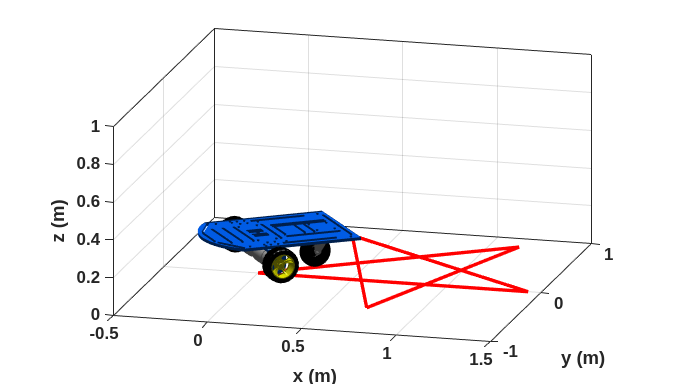


%% inciso c) – Simulación virtual 3D

% inicializamos hx, hy como historial de posiciones
hx = x1;
hy = y1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sz = get(0,'ScreenSize');
set(scene,'Position',sz);
camlight('headlight');
axis equal; grid on; box on; hold on;
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
view([15 15]);
axis([-0.5 1.5 -1 1 0 1]);

% carga del modelo
scale = 4;
MobileRobot_5;

% dibuja estado inicial
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale);
H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);

step = 1;
for k = 1:step:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end